# SÍNTESIS DE WAVE TABLE

______________________________________________________________________________________________

## Explicación

Este método se puede utilizar tanto para sonidos artificiales, generados íntegramente por cálculos informáticos, como para sonidos acústicos o grabados con un micrófono. La síntesis de wave table es una técnica basada en la lectura de datos que se almacenan en bloques de ubicaciones aledañas de memoria de computadora, llamadas tablas. Es suficiente calcular solo un ciclo de una forma de onda y luego almacenar este pequeño conjunto de muestras en la tabla donde sirve como plantilla [1].

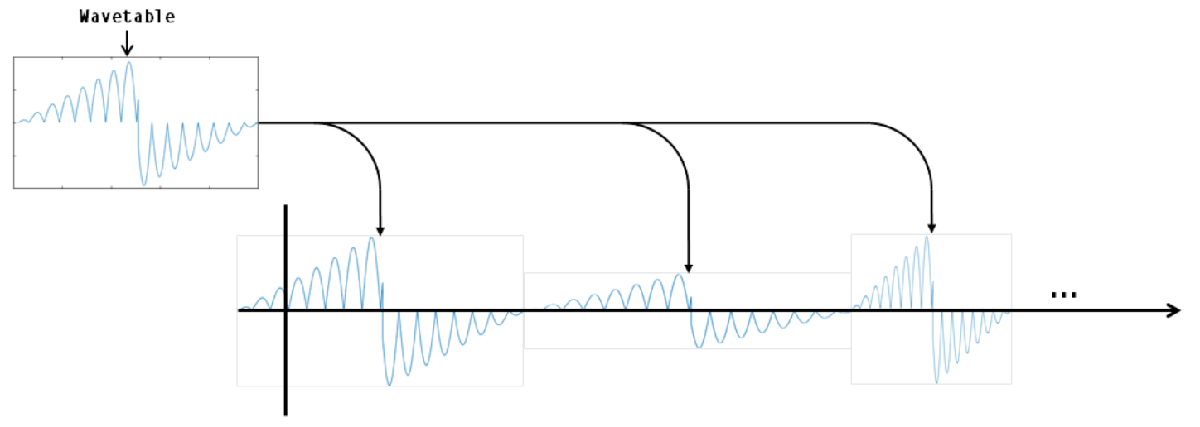

Para reproducir el sonido real, este ciclo único almacenado de la forma de onda debe volver a leerse en un bucle a una frecuencia arbitraria. El método para generar esta frecuencia arbitraria es leyendo las muestras a una frecuencia de muestreo fija de una tabla de longitud fija, pero variando el incremento de los índices de las muestras que se leerán de la tabla. En este método las únicas frecuencias que se pueden obtener de nuestro oscilador de búsqueda de tablas son aquellas que son múltiplos enteros o fracciones enteras de la frecuencia "natural" de la tabla. Pero existe un método que nos permitiría obtener cualquier frecuencia. Para entenderlo, tenemos que introducir el concepto de fase y el concepto de incremento de muestreo [1].

En la síntesis de wavetable, la fase es una variable que actúa como un puntero al índice de un elemento de la tabla (es diferente del puntero de espacio en memoria del leguaje c ó c++). El valor de la fase aumenta por la cantidad del incremento de muestreo para cada lectura de la tabla, con el fin de apuntar al índice de tabla apropiado en cada lectura subsiguiente. En realidad, el valor del incremento de muestreo determina, y es proporcional, a la frecuencia de la onda. En la mayoría de los casos, el incremento de muestreo es un número fraccionario, no un número entero. El valor de la fase también es un número real. Así, si el valor instantáneo de la fase es, por ejemplo, 10,92843, el elemento real de la tabla que se extrae es el indice de 10 porque la parte entera de la fase se toma como un puntero a un índice de elementos de la tabla [1].


$$\textrm{Incremento}\_\textrm{muestreo}=\textrm{frecuencia}\times \frac{\textrm{longitud}\_\textrm{tabla}}{\textrm{frecuencia}\_\textrm{muestreo}}$$


Cuando el valor de la fase alcanza o sobrepasa la longitud de la tabla, se necesita volver al principio para restaurar el puntero de fase a un rango útil, y esto se hace restando la longitud de la tabla [1].

Toda la técnica explicada es un método "crudo" no interpolado y esto, obviamente, introduce algún error y algo de "ruido" en la señal. Para obtener una mejor calidad de sonido (una representación más precisa de los datos / curva almacenados en la tabla) se suele emplear uno de varios métodos de interpolación, siendo el más común el método de interpolación lineal [1].

clear all, close all, clc;

## Tablas de Ondas

Antes de generear las tablas se tienen que inicializar las variables:

F = 1;                      % Frecuencia natural de la tabla
T = 1/F;                    % Tiempo total de la tabla (s) Un solo ciclo
Fs = 44100;    % Frecuencia de muestreo (Hz)
dt = 1/Fs;                  % Paso de discretización (s)
N = T/dt;                   % Número total de muestras de la tabla
n = 0:(N-1);                % Array de muestra
t = n*dt;                   % Tiempo (s)
w = 2*pi*F;                 % Frecuencia angular natural de la tabla

### **Tabla seno**

Para hallar los valores de la señal seno utilice la siguiente identidad trigonometrica [2]:


$$\sin \left(\omega t\right)=\frac{e^{j\omega t} -e^{-j\omega t} }{2j}$$


esta identidad trigonometrica sale de la identidad de euler.

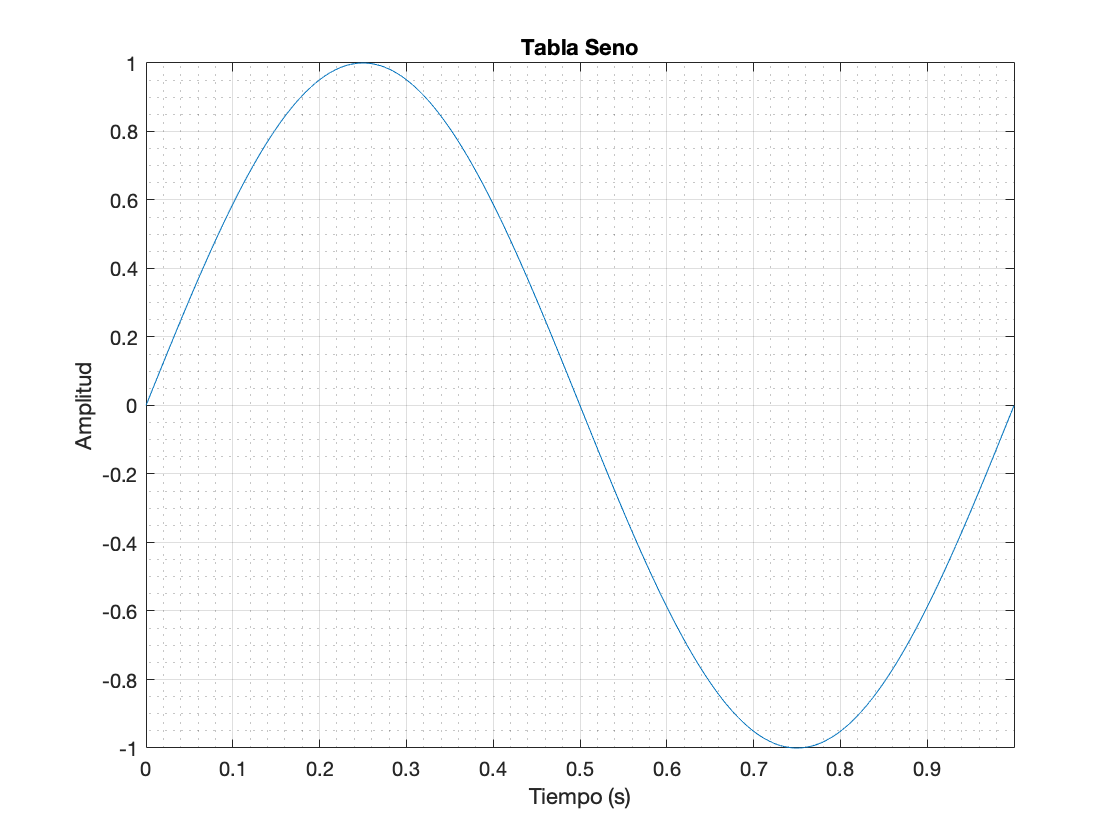

Tabla_Seno = zeros(N,1);    % Array de la señal seno de un solo ciclo
% Calculo de la señal seno con la identidad trigonometrica (Tabla seno)
for i=1:N
    Tabla_Seno(i) = (exp(w*t(i)*1j)-exp(-w*t(i)*1j))/2j;
end

% Plot de la tabla seno de un solo ciclo
plot(t,Tabla_Seno), axis('tight')
title('Tabla Seno')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
grid minor

### **Tabla Cuadrada**

En este caso para hallar los valores de la tabla cuadrada utilice la función de signo de un senoide [3]:


$$C\left(t\right)=\textrm{sgn}\left(\sin \left(\omega t\right)\right)$$


donde $C\left(t\right)$será igual a 1 cuando la senoide sea positiva y -1 cuando la senoide sea negativa.

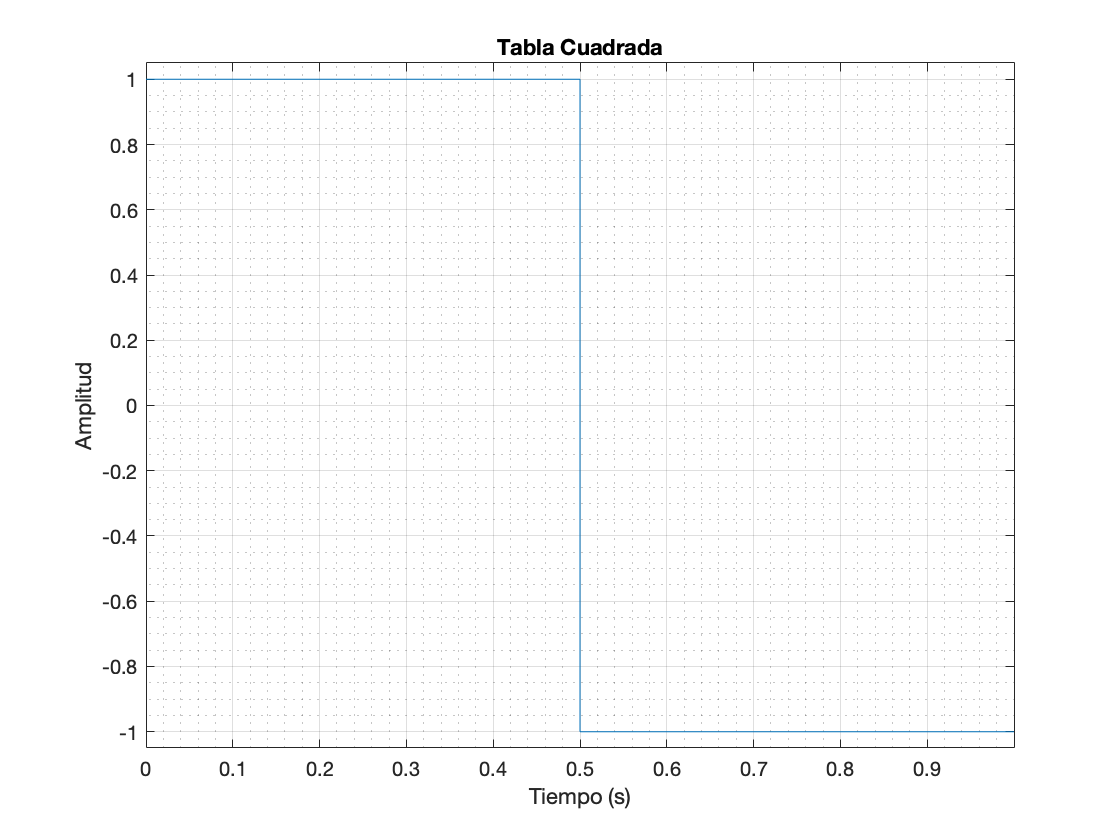

Tabla_Cuadrada = zeros(N,1); % Array de la señal cuadrada de un solo ciclo
% Calculo de la señal cuadarda con la función signo (Tabla cuadrada)
for i=1:N
    if Tabla_Seno(i) >= 0
        Tabla_Cuadrada(i) = 1;
    else
        Tabla_Cuadrada(i) = -1;
    end
end

% Plot de la tabla cuadrada de un solo ciclo
plot(t,Tabla_Cuadrada), axis('tight')
title('Tabla Cuadrada')
xlabel('Tiempo (s)')
ylabel('Amplitud')
ylim([-1.05 1.05])
grid on
grid minor

En la siguiente gráfica se puede ver que efectivamente cuando la señal seno es positiva la señal cuadrada es igual a 1, pero cuando la señal seno es negativa la señal cuadra es igual a -1.

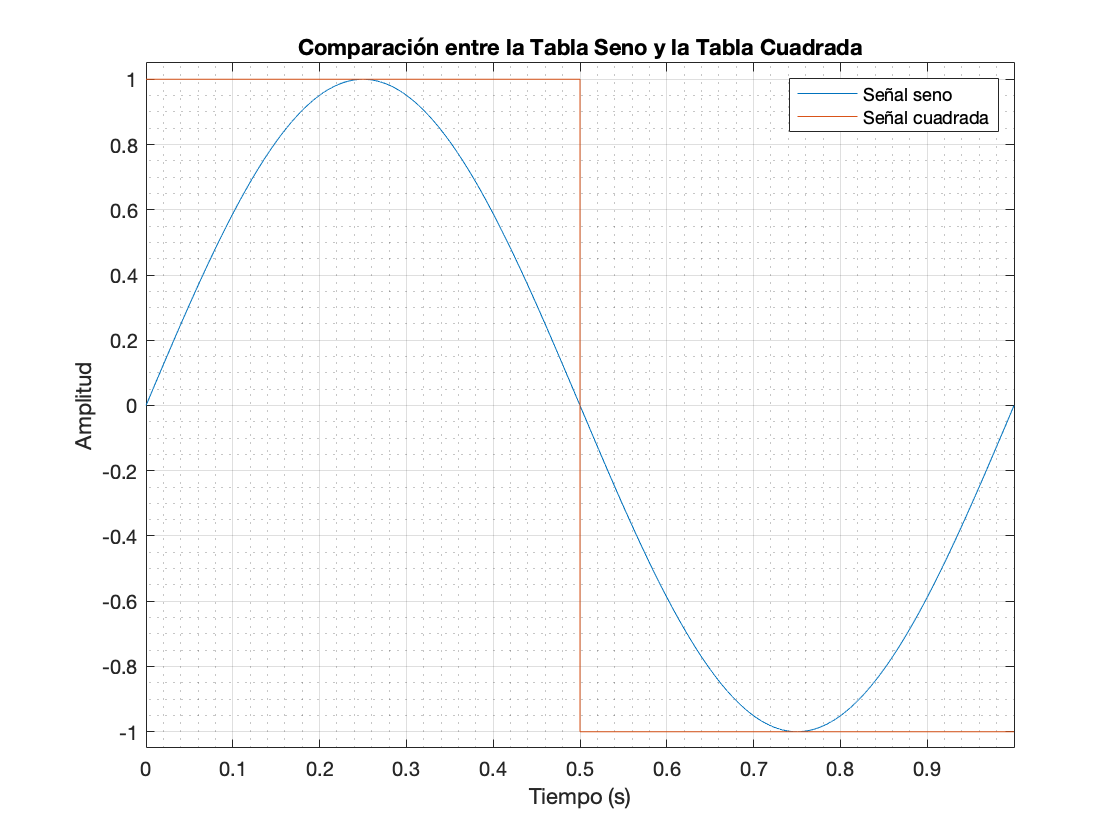

% Plot de la señal seno y la señal cuadrada
plot(t,Tabla_Seno,t,Tabla_Cuadrada), axis('tight')
title('Comparación entre la Tabla Seno y la Tabla Cuadrada')
xlabel('Tiempo (s)')
ylabel('Amplitud')
ylim([-1.05 1.05])
legend('Señal seno','Señal cuadrada')
grid on
grid minor

### **Tabla Diente Sierra**

Una forma general para calcular una señal diente sierra entre el rango de amplitud [-1 1], y con periodo T, es [4]:


$$\textrm{DS}\left(t\right)=2\left(\frac{t}{T}-\left\lfloor \frac{1}{2}+\frac{t}{T}\right\rfloor \right)$$


esta función de diente de sierra tiene la misma fase que la señal senoidal descrita anteriormente. $T$es la duración total de la señal.

$\lfloor n\rfloor$es una función de piso (floor) en el dominio del tiempo, y lo que hace es redondear hacia abajo un número decimal [5]. Por ejemplo: $\lfloor 2\ldotp 5\rfloor =2$.

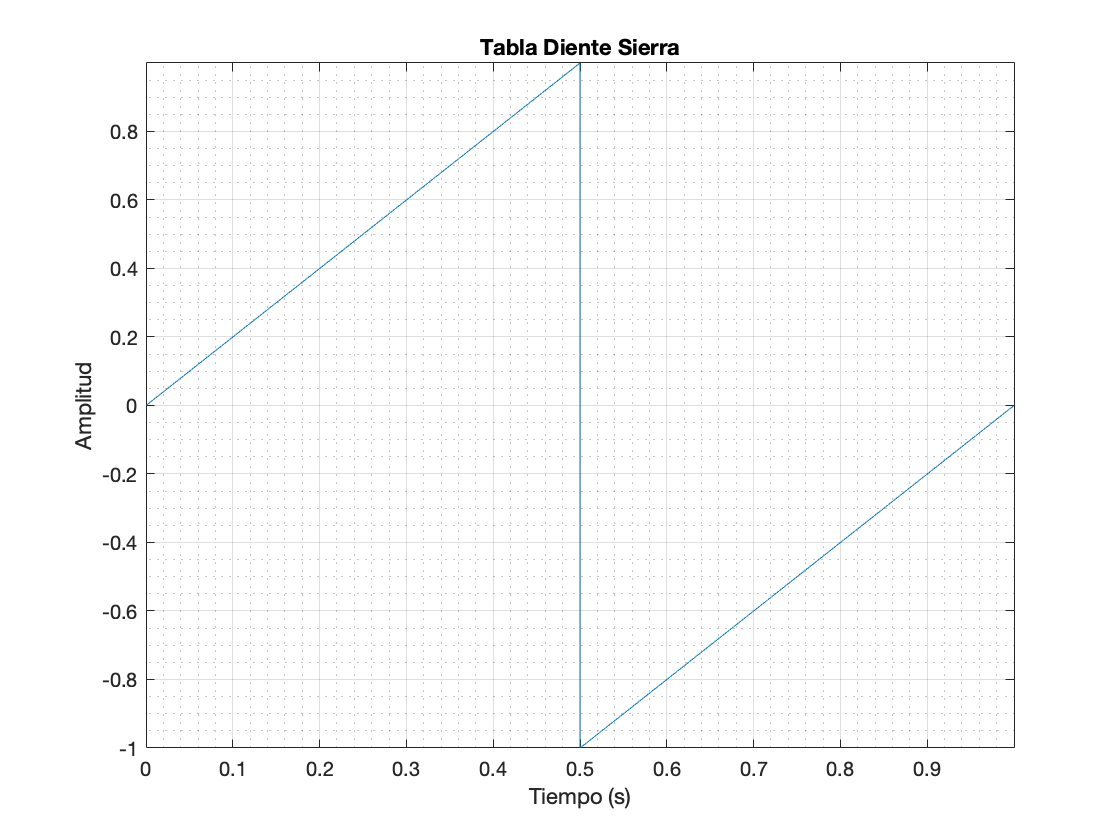

Tabla_DienteSierra = zeros(N,1); % Array de la señal diente sierra de un solo ciclo
% Calculo de la señal diente sierra con la función DS(t) (Tabla diente sierra)
for i=1:N
    Tabla_DienteSierra(i) = 2*((t(i)/T)-floor((1/2)+(t(i)/T)));
end

% Plot de la tabla diente sierra de un solo ciclo
plot(t,Tabla_DienteSierra), axis('tight')
title('Tabla Diente Sierra')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
grid minor

### **Tabla Triangular**

Para calcular una señal triangular el método es muy similar al utilizado para calcular la señal diente sierra [6].


$$T\left(t\right)=2\left|2\left(\frac{t}{T}-\left\lfloor \frac{1}{2}+\frac{t}{T}\right\rfloor \right)\right|-1$$


la expresión anterior abarca el rango entre [-1 1]. La onda triangular se puede ver como el valor absoluto de la señal diente sierra, luego se multiplica por 2 y se resta 1 para normalizar la señal en el rango establecido. 

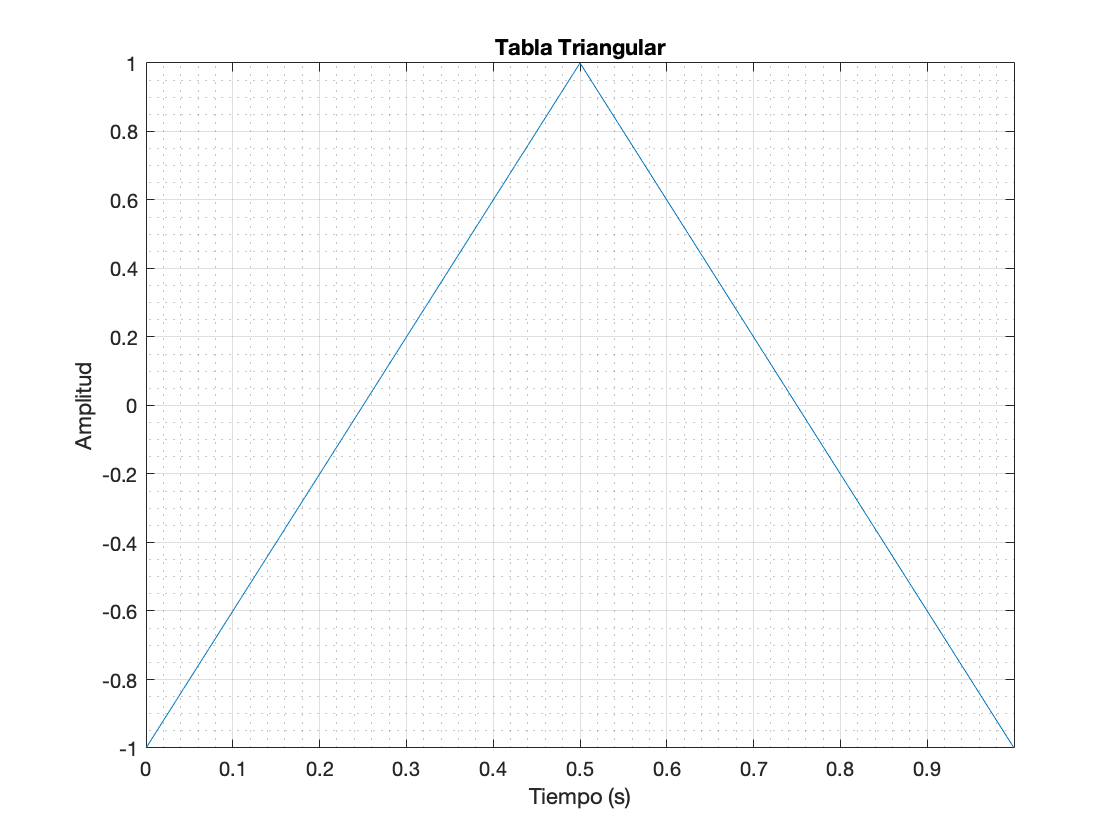

Tabla_Triangular = zeros(N,1); % Array de la señal triangular de un solo ciclo
% Calculo de la señal triangular con la función T(t) (Tabla triangular)
for i=1:N
    Tabla_Triangular(i) = (2*abs(2*((t(i)/T)-floor((1/2)+(t(i)/T)))))-1;
end

% Plot de la tabla triangular de un solo ciclo
plot(t,Tabla_Triangular), axis('tight')
title('Tabla Triangular')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
grid minor

## Tablas de Ondas con Síntesis Aditiva

### Tabla Cuadrada

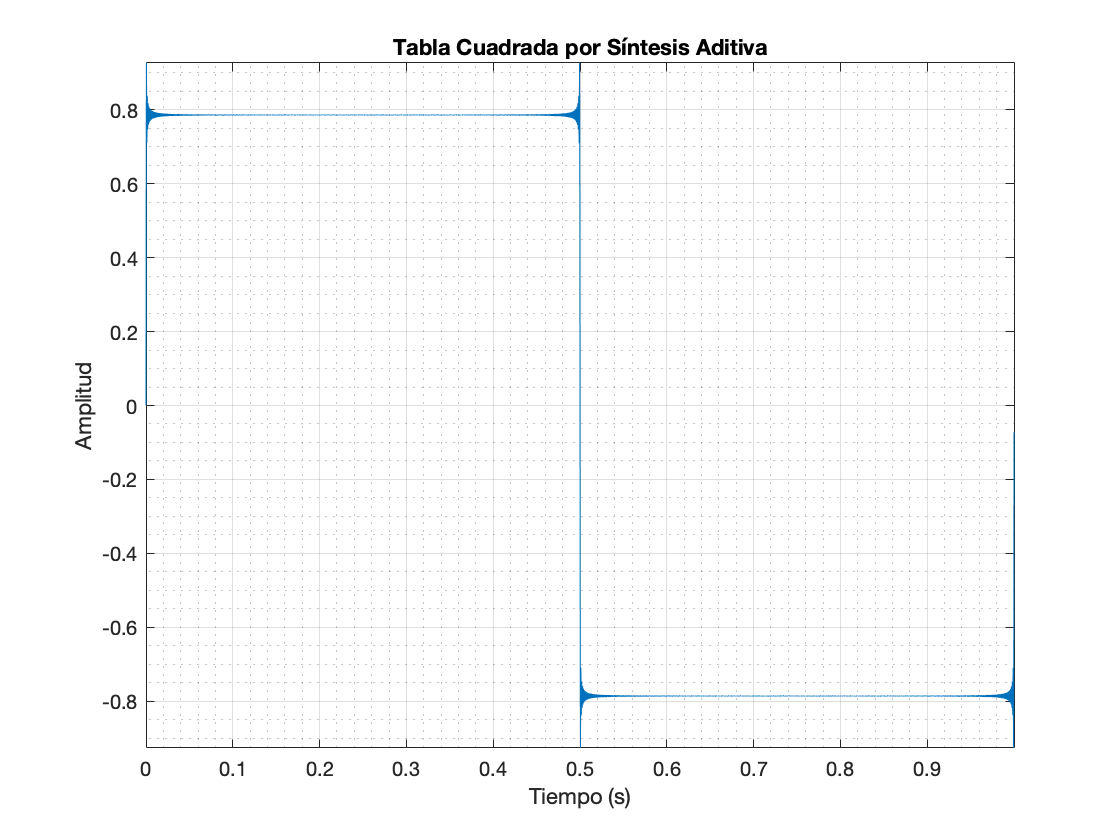

Tabla_CuadradaAdd = zeros(1,N);
for k=1:2:1009
    Tabla_CuadradaAdd = Tabla_CuadradaAdd+(sin(k*w*t)/k);
end
% Tabla_SenoAdd+((exp(k*w*t(i)*1j)-exp(-k*w*t(i)*1j))/2j)/k

Tabla_CuadradaAdd = Tabla_CuadradaAdd';
figure
plot(t,Tabla_CuadradaAdd),axis('tight')
title('Tabla Cuadrada por Síntesis Aditiva')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
grid minor

### Tabla Diente Sierra

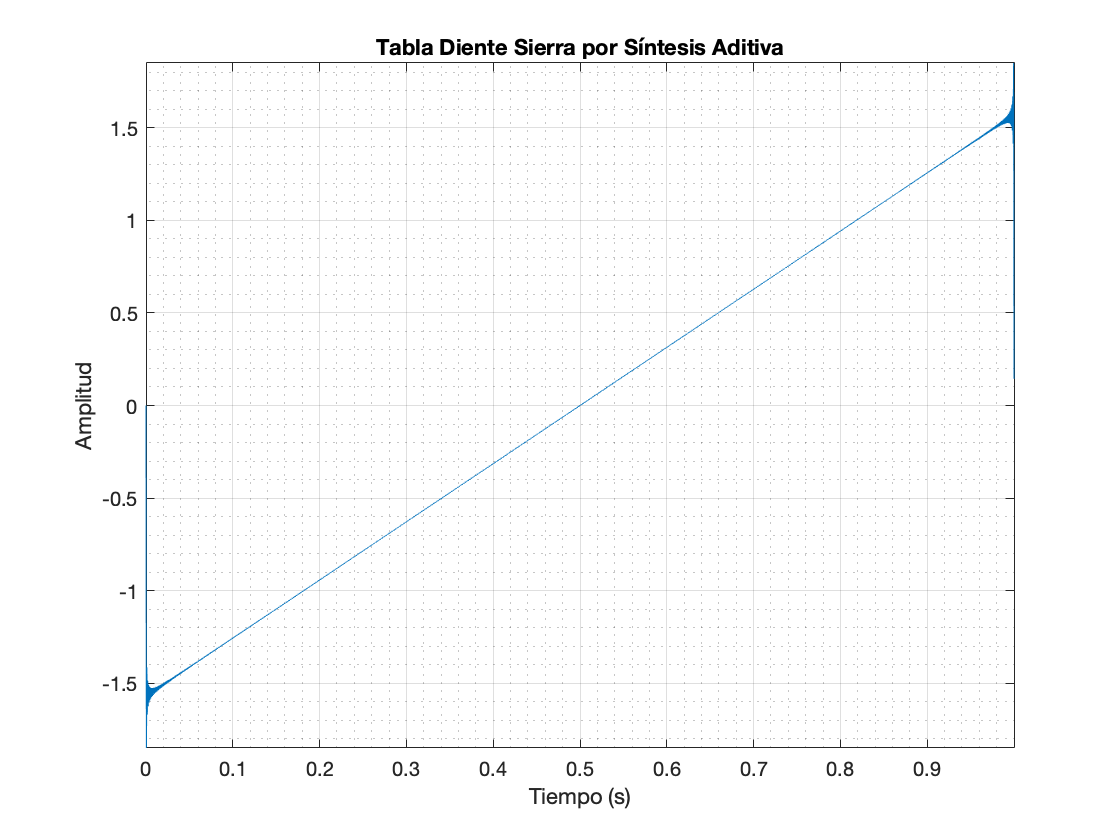

Tabla_DienteSierraAdd = zeros(1,N);
for k=1:1009
    Tabla_DienteSierraAdd = Tabla_DienteSierraAdd-((sin(k*w*t)/k));
end

Tabla_DienteSierraAdd  = Tabla_DienteSierraAdd';
figure
plot(t,Tabla_DienteSierraAdd ),axis('tight')
title('Tabla Diente Sierra por Síntesis Aditiva')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
grid minor

## Lectura de las Tablas

Para la lectura de la tabla primero se establece la forma de onda, luego se establece la frecuencia arbitraria que se desea reproducir y la duración de la señal.

onda = "Cuadrada";             % Forma de onda
f =125.43;       % Frecuencia arbitraria
duracion = 1;   % Duración de la señal

Luego de establecer estos valores se calcula el incrimento de muestreo para la lectura de la tabla. El puntero al indice de la tabla (fase) aumenta a partir del entero de este incremento, pero cuando la fase supere el tamaño de la tabla el valor de la fase en ese intante se resta por el tamaño de la tabla.

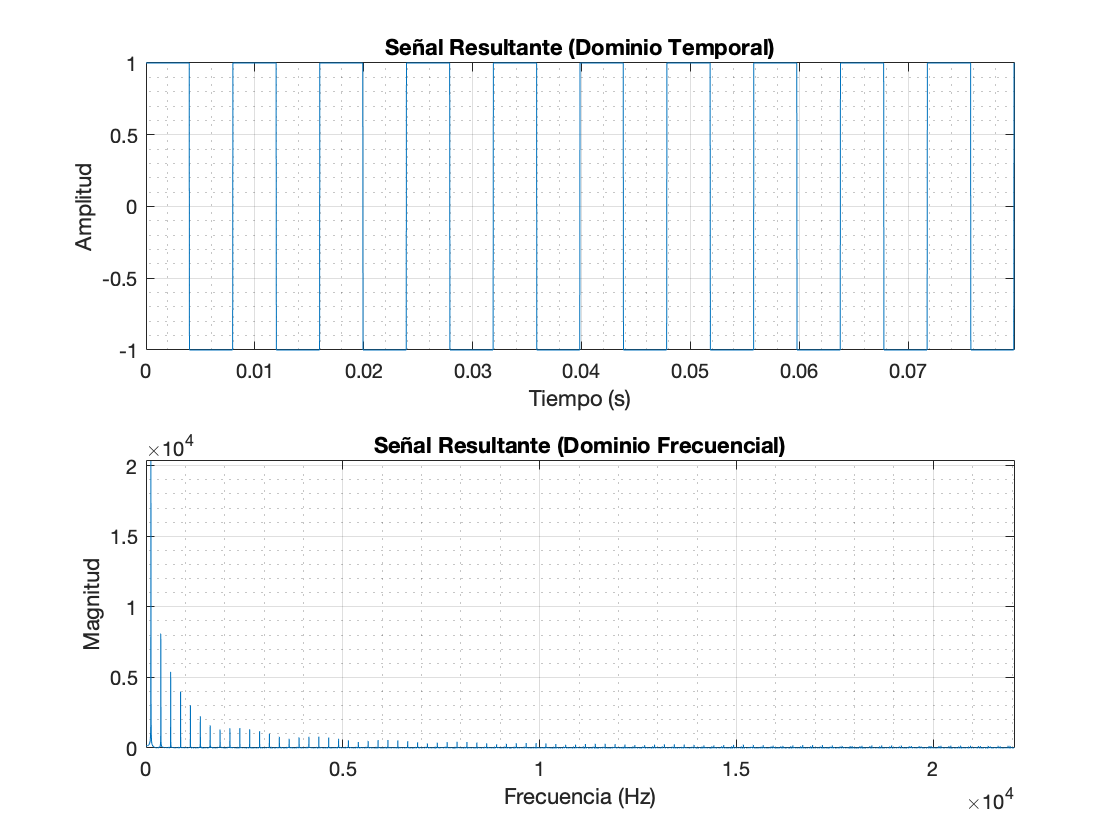

incremento_de_muestreo = f*(N/Fs);     % Incremento de muestreo
senal = zeros(duracion*N,1);           % Señal resultante
fase = 1;                              % Puntero al indice (fase)

% Lectura de la tabla dependiento la forma de onda
switch onda
    case "Seno"
        for i= 1:(duracion*N)
            ibase = floor(fase);
            if ibase == 0
                ibase = N;
            end
            senal(i) = Tabla_Seno(ibase);
            fase = fase+incremento_de_muestreo;
            while fase > N   % Cuando la fase sobrepasa la longitud de la tabla
                fase = fase-N;
            end
        end
    case "Cuadrada"
        for i= 1:(duracion*N)
            ibase = floor(fase);
            if ibase == 0
                ibase = N;
            end
            senal(i) = Tabla_Cuadrada(ibase);
            fase = fase+incremento_de_muestreo;
            while fase > N   % Cuando la fase sobrepasa la longitud de la tabla
                fase = fase-N;
            end
        end
    case "Cuadrada aditiva"
        for i= 1:(duracion*N)
            ibase = floor(fase);
            if ibase == 0
                ibase = N;
            end
            senal(i) = Tabla_CuadradaAdd(ibase);
            fase = fase+incremento_de_muestreo;
            while fase > N   % Cuando la fase sobrepasa la longitud de la tabla
                fase = fase-N;
            end
        end
    case "Diente sierra"
        for i= 1:(duracion*N)
            ibase = floor(fase);
            if ibase == 0
                ibase = N;
            end
            senal(i) = Tabla_DienteSierra(ibase);
            fase = fase+incremento_de_muestreo;
            while fase > N   % Cuando la fase sobrepasa la longitud de la tabla
                fase = fase-N;
            end
        end
    case "Diente sierra aditiva"
        for i= 1:(duracion*N)
            ibase = floor(fase);
            if ibase == 0
                ibase = N;
            end
            senal(i) = Tabla_DienteSierraAdd(ibase);
            fase = fase+incremento_de_muestreo;
            while fase > N   % Cuando la fase sobrepasa la longitud de la tabla
                fase = fase-N;
            end
        end
    case "Triangular"
        for i= 1:(duracion*N)
            ibase = floor(fase);
            if ibase == 0
                ibase = N;
            end
            senal(i) = Tabla_Triangular(ibase);
            fase = fase+incremento_de_muestreo;
            while fase > N   % Cuando la fase sobrepasa la longitud de la tabla
                fase = fase-N;
            end
        end
end

% Plot de la señal resultante en el tiempo y el plor muestra como máximo 10 ciclos
n2 = 0:(N*duracion)-1;
t2 = n2*dt;
figure
subplot(211)
plot(t2,senal), axis('tight')
title('Señal Resultante (Dominio Temporal)')
xlabel('Tiempo (s)')
ylabel('Amplitud')
xlim([0 (1/f)*10])
grid on
grid minor

% Plot del dominio frecuencial de la señal resultante
senalDFT = fft(senal);     % DFT de la señal resultante
df = Fs/N;                 % Paso en frecuencia
k = n2;                    % BINES
freq = k*df;               % Frecuencia
subplot(212)
plot(freq,abs(senalDFT)), axis('tight')
title('Señal Resultante (Dominio Frecuencial)')
xlabel('Frecuencia (Hz)')
ylabel('Magnitud')
xlim([0 Fs/2])
grid on
grid minor

## Análisis del Incremento de Muestreo

Se tomo la desición que la frecuencia natural de la tabla sea igual a 1 Hz para que el valor del incremento de muestreo sea igual a la frecuencia arbitraria. Si la frecuencia natural de la tabla es de 1 Hz el periodo de la tabla es igual a 1 seg (un solo ciclo), por ende la longitud de la tabla es igual a la frecuencia de muestreo. En la ecuación del incremento de muestreo si longitud de la tabla es igual a la frecuencia de muestreo, este incremento de lectura de la tabla siempre es igual a la frecuencia arbitraria. 

La tecnica de wave table funciona muy bien para frecuencias bajas y medias, porque entre mayor sea la frecuencia arbitraria mayor va a ser el incremento de muestreo y eso causa que la fase tome menos muestras de la tabla. Entre menos muestras tome la fase de la tabla, la representación de la señal real es menos fiel. Esto lleva a que cuando la frecuencia arbitraria es igual a la frecuencia de Nyquist la fase solo toma 2 muestras de la tabla, y la forma de onda sea parecida a una onda triangular. Debido a todo esto se puede ver la distorsión que se genera en la señal debido a la deformación de la onda por la menor cantidad de muestras tomadas. 

Una posible solución a este problema de muestras tomadas por la fase es el aumento de la frecuencia de muestreo, dado que la longitud de la tabla es igual a la frecuencia de muestreo y así la fase puede tomar mas cantidad de muestras. Pero al aumentar la frecuencia de muestreo también aumenta el costo computacional.

Otro problema con esta tecnica es cuando la frecuencia arbitraria toma un valor decimal, porque el incremento de muestreo toma ese mismo valor decimal y por ende la fase incrementa en un valor decimal. Hay dos soluciones a este problema: El primero es el método de truncamiento que consiste en tomar el valor de piso (floor) de la fase en ese instante, este método es el que se utilizó anteriormente para la lectura de la tabla. Otro método es la interpolación lineal que consiste en calcular la salida de la tabla en un puntero al índice (fase) fraccional. La interpolación lineal se explica desde la pagina 302 del libro [1].


$$\sum_{i=1}^{N-1} f\left\lbrack i\right\rbrack =\textrm{Tabla}\left\lfloor \textrm{fase}\right\rfloor +\left(\textrm{fase}-\left\lfloor \textrm{fase}\right\rfloor \right)*\left(\textrm{Tabla}\left\lfloor \textrm{fase}+1\right\rfloor -\textrm{Tabla}\left\lfloor \textrm{fase}\right\rfloor \right)$$


donde la fase es un indice decimal.

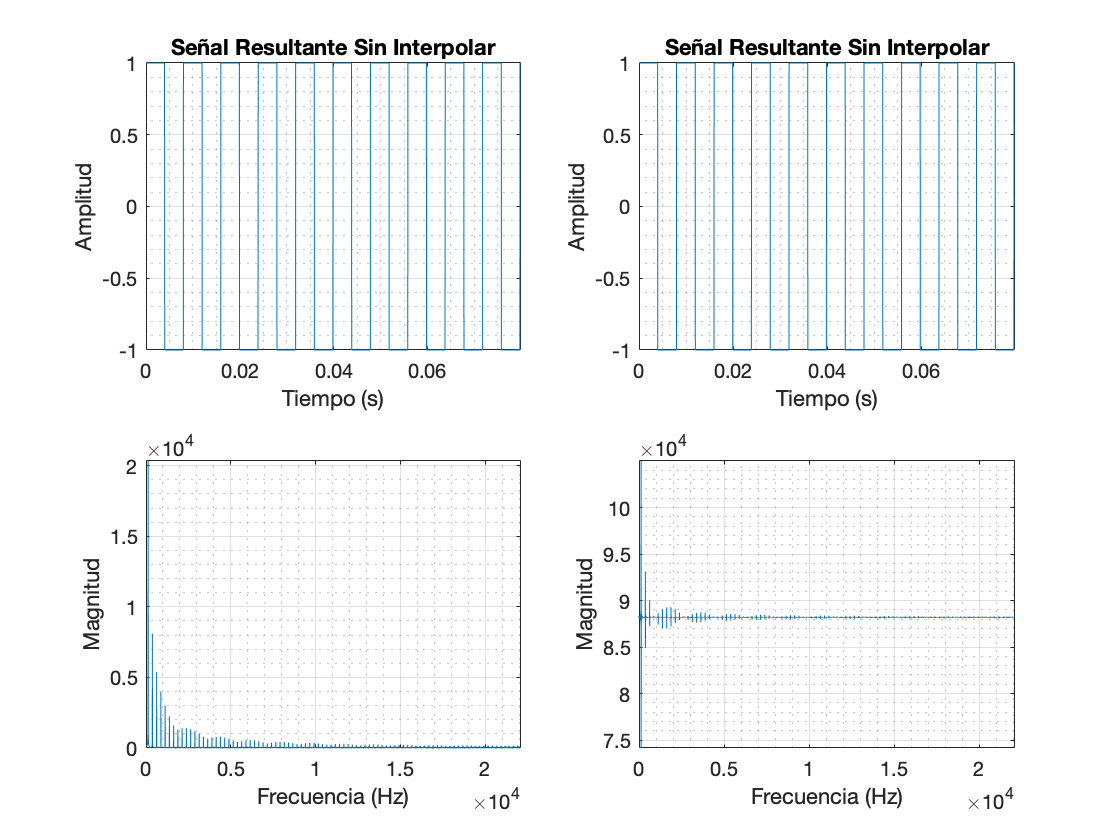

% Lectura de la tabla con interpolación lineal
senalint = zeros(N*duracion,1); % Señal interpolada
fase = 1;
switch onda
    case "Seno"
        for i= 1:N*duracion
            ibase = floor(fase);
            inext = ibase+1;
            if ibase == 0
                ibase = N;
            end
            if inext > N
                inext = inext-N;
            end
            frac = fase-ibase;
            val = Tabla_Seno(ibase);
            slope = Tabla_Seno(inext)-val;
            val = val+(frac*slope);
            senalint(i) = val;
            fase = fase+incremento_de_muestreo;
            while fase > N
                fase = fase-N;
            end
        end
    case "Cuadrada"
        for i= 1:N*duracion
            ibase = floor(fase);
            inext = ibase+1;
            if ibase == 0
                ibase = N;
            end
            if inext > N
                inext = inext-N;
            end
            frac = fase-ibase;
            val = Tabla_Cuadrada(ibase);
            slope = Tabla_Cuadrada(inext)-val;
            val = val+(frac*slope);
            senalint(i) = val;
            fase = fase+incremento_de_muestreo;
            while fase > N
                fase = fase-N;
            end
        end
    case "Cuadrada aditiva"
        for i= 1:N*duracion
            ibase = floor(fase);
            inext = ibase+1;
            if ibase == 0
                ibase = N;
            end
            if inext > N
                inext = inext-N;
            end
            frac = fase-ibase;
            val = Tabla_CuadradaAdd(ibase);
            slope = Tabla_CuadradaAdd(inext)-val;
            val = val+(frac*slope);
            senalint(i) = val;
            fase = fase+incremento_de_muestreo;
            while fase > N
                fase = fase-N;
            end
        end
    case "Diente sierra"
        for i= 1:N*duracion
            ibase = floor(fase);
            inext = ibase+1;
            if ibase == 0
                ibase = N;
            end
            if inext > N
                inext = inext-N;
            end
            frac = fase-ibase;
            val = Tabla_DienteSierra(ibase);
            slope = Tabla_DienteSierra(inext)-val;
            val = val+(frac*slope);
            senalint(i) = val;
            fase = fase+incremento_de_muestreo;
            while fase > N
                fase = fase-N;
            end
        end
    case "Diente sierra aditiva"
        for i= 1:N*duracion
            ibase = floor(fase);
            inext = ibase+1;
            if ibase == 0
                ibase = N;
            end
            if inext > N
                inext = inext-N;
            end
            frac = fase-ibase;
            val = Tabla_DienteSierraAdd(ibase);
            slope = Tabla_DienteSierraAdd(inext)-val;
            val = val+(frac*slope);
            senalint(i) = val;
            fase = fase+incremento_de_muestreo;
            while fase > N
                fase = fase-N;
            end
        end
    case "Triangular"
        for i= 1:N*duracion
            ibase = floor(fase);
            inext = ibase+1;
            if ibase == 0
                ibase = N;
            end
            if inext > N
                inext = inext-N;
            end
            frac = fase-ibase;
            val = Tabla_Triangular(ibase);
            slope = Tabla_Triangular(inext)-val;
            val = val+(frac*slope);
            senalint(i) = val;
            fase = fase+incremento_de_muestreo;
            while fase > N
                fase = fase-N;
            end
        end
end

% Plot de la señal resultante en el tiempo sin interpolar
figure
subplot(221)
plot(t2,senal), axis('tight')
title('Señal Resultante Sin Interpolar')
xlabel('Tiempo (s)')
ylabel('Amplitud')
xlim([0 (1/f)*10])
grid on
grid minor
subplot(223)
plot(freq,abs(senalDFT)), axis('tight')
xlabel('Frecuencia (Hz)')
ylabel('Magnitud')
xlim([0 Fs/2])
grid on
grid minor

% Plot de la señal resultante en el tiempo interpolada
subplot(222)
plot(t2,senalint), axis('tight')
title('Señal Resultante Sin Interpolar')
xlabel('Tiempo (s)')
ylabel('Amplitud')
xlim([0 (1/f)*10])
grid on
grid minor
senalintDFT = fft(senalint);
subplot(224)
plot(freq,abs(senalintDFT)), axis('tight')
xlabel('Frecuencia (Hz)')
ylabel('Magnitud')
xlim([0 Fs/2])
grid on
grid minor

Error cuadratico medio entre la señal por el método de truncamiento y la señal interpolada linealmente:

MSE = immse(senal,senalint) % Error cuadratico medio

MSE = 1.7640e+05

Cuando la frecuencia arbitraria es un valor decimal el error cuadratico medio entre las dos señales es un valor muy cercano a cero. Pero la interpolación lineal si esta aproximando los indices decimales de la fase y puede ser muy util para hacer una representación aprximada de las frecuencias arbitrarias con decimales.

**Nota:** Cuando la frecuencia arbitraria es un valor entero el MSE es igual a cero porque la interpolación lineal no tiene decimales por aproximar y por ende los calculos son iguales.

______________________________________________________________________________________________

## Referencias

[1] Boulanger, R., & Lazzarini, V. (2010). The Audio Programming Book. In *Audio*. [https://books.google.com.co/books?id=QsR3RAAACAAJ&printsec=frontcover&hl=es&source=gbs_ge_summary_r&cad=0#v=onepage&q&f=false](https://books.google.com.co/books?id=QsR3RAAACAAJ&printsec=frontcover&hl=es&source=gbs_ge_summary_r&cad=0#v=onepage&q&f=false)

[2] MATLAB. (n.d.). *Sine of argument in degrees*. Retrieved September 24, 2021, from [https://la.mathworks.com/help/matlab/ref/sin.html](https://la.mathworks.com/help/matlab/ref/sin.html)

[3] Wikipedia. (2017). *Square wave*. 26 October. [https://en.wikipedia.org/wiki/Square_wave#Definitions](https://en.wikipedia.org/wiki/Square_wave#Definitions)

[4] Wikipedia. (2011). *Sawtooth wave*. [https://en.wikipedia.org/wiki/Sawtooth_wave](https://en.wikipedia.org/wiki/Sawtooth_wave)

[5] Wikipedia. (2021). *Floor and ceiling functions*. [https://en.wikipedia.org/wiki/Floor_and_ceiling_functions](https://en.wikipedia.org/wiki/Floor_and_ceiling_functions)

[6] Wikipedia. (n.d.). *Triangle wave*. Retrieved September 24, 2021, from [https://en.wikipedia.org/wiki/Triangle_wave#Definition](https://en.wikipedia.org/wiki/Triangle_wave#Definition)